Voici un code générant les N+1 points de Tchebyshev à l'aide de la formule: $x_k = \cos\left(\frac{k \pi}{N}\right), \quad k = 0, \dots, N$.

On traçe aussi l'arc de cercle supérieur de [-1,1] avec les N points equidistants pour comprendre l'orgine de ces points

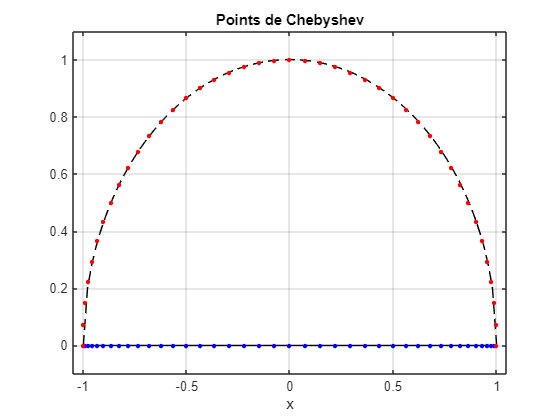

% Ce script génère et trace les points de Chebyshev de première espèce

N = 42;
k = 0:N;
x = cos(pi * k / N); % Points de Chebyshev
y = sin(acos(x)); % Hauteur des points sur l'arc de cercle

xlin = linspace(-1,1);
ylin = sin(acos(xlin)); %pour tracer l'arc de cercle

plot(xlin, ylin, "--black");
hold on
plot(xlin, zeros(100),'-black');
plot(x, zeros(size(x)), 'b.', ...
    MarkerSize=10)
hold on
plot(x, y, "r.", ...
    MarkerSize=10)
hold off
title('Points de Chebyshev')
xlabel('x')
ylim([-0.1, 1.1])
xlim([-1.05,1.05])
grid on